# Create Deep Learning Network Architecture with Pretrained Parameters

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 12-May-2025 13:09:56

## Load Network Parameters

Load network parameters like weights, biases, or layers unsupported for network code generation from the stored parameters file.

params = load("F:\code\My GitHub\voice_based_ai_models\params_2025_05_12__13_09_49.mat");

## Create dlnetwork

Create the dlnetwork variable to contain the network layers.

net = dlnetwork;

## Add Layer Branches

Add branches to the dlnetwork. Each branch is a linear array of layers.

tempNet = [
    inputLayer([40 4 NaN],"CTB","Name","input")
    audio.ai.vadnet.layers.reformatLayer("Name","reformat")
    audio.ai.vadnet.layers.layerNormalizationElementwiseLayer("Name","norm1","DDimension",2,"Bias",params.norm1.Bias,"Scale",params.norm1.Scale)
    audio.ai.vadnet.layers.paddingLayer("Name","cnn1.pad1")
    convolution2dLayer([3 3],16,"Name","cnn1.conv1","Bias",params.cnn1_conv1.Bias,"Weights",params.cnn1_conv1.Weights)
    audio.ai.vadnet.layers.layerNormalizationElementwiseLayer("Name","cnn1.norm1","Bias",params.cnn1_norm1.Bias,"Scale",params.cnn1_norm1.Scale)
    leakyReluLayer(0.01,"Name","cnn1.act1")
    audio.ai.vadnet.layers.paddingLayer("Name","cnn1.pad2")
    convolution2dLayer([3 3],16,"Name","cnn1.conv2","Bias",params.cnn1_conv2.Bias,"Weights",params.cnn1_conv2.Weights)
    audio.ai.vadnet.layers.layerNormalizationElementwiseLayer("Name","cnn1.norm2","Bias",params.cnn1_norm2.Bias,"Scale",params.cnn1_norm2.Scale)
    leakyReluLayer(0.01,"Name","cnn1.act2")
    maxPooling2dLayer([1 2],"Name","cnn1.pool1","Stride",[1 2])
    dropoutLayer(0.15,"Name","cnn1.dropout")
    audio.ai.vadnet.layers.paddingLayer("Name","cnn2.pad1")
    convolution2dLayer([3 3],32,"Name","cnn2.conv1","Bias",params.cnn2_conv1.Bias,"Weights",params.cnn2_conv1.Weights)
    audio.ai.vadnet.layers.layerNormalizationElementwiseLayer("Name","cnn2.norm1","Bias",params.cnn2_norm1.Bias,"Scale",params.cnn2_norm1.Scale)
    leakyReluLayer(0.01,"Name","cnn2.act1")
    audio.ai.vadnet.layers.paddingLayer("Name","cnn2.pad2")
    convolution2dLayer([3 3],32,"Name","cnn2.conv2","Bias",params.cnn2_conv2.Bias,"Weights",params.cnn2_conv2.Weights)
    audio.ai.vadnet.layers.layerNormalizationElementwiseLayer("Name","cnn2.norm2","Bias",params.cnn2_norm2.Bias,"Scale",params.cnn2_norm2.Scale)
    leakyReluLayer(0.01,"Name","cnn2.act2")
    maxPooling2dLayer([1 2],"Name","cnn2.pool2","Stride",[1 2])
    dropoutLayer(0.15,"Name","cnn2.droput")
    audio.ai.vadnet.layers.reformatAndFlattenLayer("Name","flatten")];
net = addLayers(net,tempNet);

tempNet = gruLayer(32,"Name","gru1.forward","BiasLearnRateFactor",0,"InputWeightsLearnRateFactor",0,"RecurrentWeightsLearnRateFactor",0,"ResetGateMode","recurrent-bias-after-multiplication","Bias",params.gru1_forward.Bias,"HiddenState",params.gru1_forward.HiddenState,"InputWeights",params.gru1_forward.InputWeights,"RecurrentWeights",params.gru1_forward.RecurrentWeights);
net = addLayers(net,tempNet);

tempNet = [
    audio.ai.vadnet.layers.reverseTimeLayer("Name","gru1.reversetime1")
    gruLayer(32,"Name","gru1.reverse","BiasLearnRateFactor",0,"InputWeightsLearnRateFactor",0,"RecurrentWeightsLearnRateFactor",0,"ResetGateMode","recurrent-bias-after-multiplication","Bias",params.gru1_reverse.Bias,"HiddenState",params.gru1_reverse.HiddenState,"InputWeights",params.gru1_reverse.InputWeights,"RecurrentWeights",params.gru1_reverse.RecurrentWeights)
    audio.ai.vadnet.layers.reverseTimeLayer("Name","gru1.reversetime2")];
net = addLayers(net,tempNet);

tempNet = concatenationLayer(1,2,"Name","gru1.concat");
net = addLayers(net,tempNet);

tempNet = gruLayer(32,"Name","gru2.forward","BiasLearnRateFactor",0,"InputWeightsLearnRateFactor",0,"RecurrentWeightsLearnRateFactor",0,"ResetGateMode","recurrent-bias-after-multiplication","Bias",params.gru2_forward.Bias,"HiddenState",params.gru2_forward.HiddenState,"InputWeights",params.gru2_forward.InputWeights,"RecurrentWeights",params.gru2_forward.RecurrentWeights);
net = addLayers(net,tempNet);

tempNet = [
    audio.ai.vadnet.layers.reverseTimeLayer("Name","gru2.reversetime1")
    gruLayer(32,"Name","gru2.reverse","BiasLearnRateFactor",0,"InputWeightsLearnRateFactor",0,"RecurrentWeightsLearnRateFactor",0,"ResetGateMode","recurrent-bias-after-multiplication","Bias",params.gru2_reverse.Bias,"HiddenState",params.gru2_reverse.HiddenState,"InputWeights",params.gru2_reverse.InputWeights,"RecurrentWeights",params.gru2_reverse.RecurrentWeights)
    audio.ai.vadnet.layers.reverseTimeLayer("Name","gru2.reversetime2")];
net = addLayers(net,tempNet);

tempNet = [
    concatenationLayer(1,2,"Name","gru2.concat")
    fullyConnectedLayer(16,"Name","dnn.fc1","Bias",params.dnn_fc1.Bias,"Weights",params.dnn_fc1.Weights)
    batchNormalizationLayer("Name","dnn.bnorm1","Offset",params.dnn_bnorm1.Offset,"Scale",params.dnn_bnorm1.Scale,"TrainedMean",params.dnn_bnorm1.TrainedMean,"TrainedVariance",params.dnn_bnorm1.TrainedVariance)
    leakyReluLayer(0.01,"Name","dnn.act1")
    dropoutLayer(0.15,"Name","dnn.dropout1")
    fullyConnectedLayer(16,"Name","dnn.fc2","Bias",params.dnn_fc2.Bias,"Weights",params.dnn_fc2.Weights)
    batchNormalizationLayer("Name","dnn.bnorm2","Offset",params.dnn_bnorm2.Offset,"Scale",params.dnn_bnorm2.Scale,"TrainedMean",params.dnn_bnorm2.TrainedMean,"TrainedVariance",params.dnn_bnorm2.TrainedVariance)
    leakyReluLayer(0.01,"Name","dnn.act2")
    dropoutLayer(0.15,"Name","dnn.dropout2")
    fullyConnectedLayer(1,"Name","dnn.fc3","Bias",params.dnn_fc3.Bias,"Weights",params.dnn_fc3.Weights)
    sigmoidLayer("Name","dnn.sigmoid")];
net = addLayers(net,tempNet);

% clean up helper variable
clear tempNet;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

net = connectLayers(net,"flatten","gru1.forward");
net = connectLayers(net,"flatten","gru1.reversetime1");
net = connectLayers(net,"gru1.forward","gru1.concat/in1");
net = connectLayers(net,"gru1.reversetime2","gru1.concat/in2");
net = connectLayers(net,"gru1.concat","gru2.forward");
net = connectLayers(net,"gru1.concat","gru2.reversetime1");
net = connectLayers(net,"gru2.forward","gru2.concat/in1");
net = connectLayers(net,"gru2.reversetime2","gru2.concat/in2");
net = initialize(net);

## Plot Layers

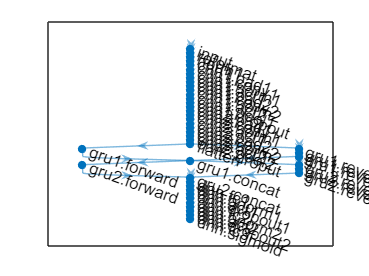

plot(net);